
% figure R vs Direction %

clear all;
close all;

load('E:\Data\2024-11-10\BxByScan.mat');
clear Bx;
clear By;



conversionx = 108/115/20*1e3;
conversiony = 108/82/20*1e3;

Bx = (BxBy(:,1))*conversionx;   % mA --- mrad
By = (BxBy(:,2))*conversiony;   % mA --- mrad

weight = 1./err.^2;


ratio_mean = sum(ratio.*weight,2)./sum(weight,2);
err_mean = sqrt(sum(weight.* ((ratio-ratio_mean).^2 + 1./weight),2) ./ sum(weight,2));


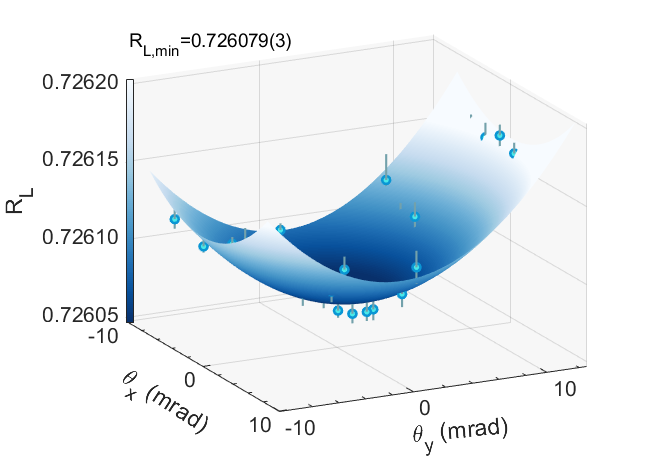


%% 拟合: '无标题拟合 1'。
w = 1./err_mean.^2;
[xData, yData, zData, weights] = prepareSurfaceData(Bx, By, ratio_mean, w);

% 设置 fittype 和选项。
ft1 = fittype( 'a1*(x-c1)^2+a2*(y-c2)^2+d',...
    'independent', {'x', 'y'}, 'dependent', 'z' );
opts1 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts1.Display = 'Off';
opts1.Lower = [-1/conversionx^2 -1/conversiony^2 -1*conversionx -1.5*conversiony 0.725];
opts1.Upper = [5/conversionx^2 5/conversiony^2 1*conversionx 1*conversiony 0.727];
opts1.StartPoint = [2e-7 4e-7 0.2*conversionx -0.3*conversiony 0.72607];
opts1.Weights = weights;

% 对数据进行模型拟合。
[fitresult, gof1] = fit( [xData, yData], zData, ft1, opts1 );
a1 = fitresult.a1;
a2 = fitresult.a2;
c1 = fitresult.c1;
c2 = fitresult.c2;
R_min = fitresult.d;

interval = confint(fitresult);
a1_sigma = (interval(2,1)-interval(1,1))/4;
a2_sigma = (interval(2,2)-interval(1,2))/4;
c1_sigma = (interval(2,3)-interval(1,3))/4;
c2_sigma = (interval(2,4)-interval(1,4))/4;
R_sigma = (interval(2,5)-interval(1,5))/4;



% 计算 Chi square %
chi_square1 = 0;
for k1 = 1:length(ratio_mean)
    temp1(k1) = (ratio_mean(k1)-fitresult(Bx(k1),By(k1)))^2;
    chi_square1 = chi_square1 + w(k1)*temp1(k1);
end
chi_square1 = chi_square1/(length(ratio_mean)-5);


f1 = figure('Position',[482,478,649,462]); %hold on;

Bx_low = min(Bx)*0.6;
Bx_high = max(Bx)*1.1;
By_low = min(By)*1.1;
By_high = max(By)*0.9;

[Bx_surf,By_surf] = meshgrid(Bx_low:(Bx_high-Bx_low)/100:Bx_high,...
    By_low:(By_high-By_low)/100:By_high);

ratio_surf = fitresult(Bx_surf,By_surf);

as1 = axes('Parent',f1);
hold(as1,'on');

s1 = plot( fitresult );%, ratio_mean );
s1 = surf(Bx_surf,By_surf,ratio_surf,'Parent',as1);
shading interp;
alpha(s1,1);
%cMap = getPyPlot_cMap('Greens',128,0,"C:\Users\USTC\AppData\Local\Programs\Python\Python313\python");
cMap = getPyPlot_cMap('Blues',128,0,"C:\Users\USTC\AppData\Local\Programs\Python\Python39\python");
temp = cMap';
temp = fliplr(temp);
cMap1 = temp';
colormap(cMap1);
clim([0.726085 0.72616]);
colorbar(as1,'Ticks',[0.72605 0.72620],'TickLabels',{},...
    'Position',[0.19355,0.3000,0.013,0.5285]);

% s1(2).MarkerEdgeColor = [0.04 0.59 0.83];
% s1(2).MarkerFaceColor = [0.29 0.91 0.91];
% 'Color',[0.45 0.63 0.67]
% s1(2).LineWidth = 2;

xlim([c1-10 c1+10]);
xticks([c1-10 c1 c1+10]);
xticklabels({-10 0 10});
ylim([c2-10 c2+13]);
yticks([c2-10 c2 c2+10]);
yticklabels({-10 0 10});
zlim([0.726047 0.726203]);
zticks([0.72605:5e-5:0.72620]);
zticklabels({'0.72605','0.72610','0.72615','0.72620'});

xlabel('\theta_x (mrad)','Rotation',-33,...
    'Position',[9.56746,-30.45285,0.72602]);
ylabel('\theta_y (mrad)','Rotation',5,...
    'Position',[18.30510,-20.74438,0.72603]);
zlabel('R_L');

%daspect auto;

%% 绘制原始数据 %%

% E1 = plot3((Bx-c1)/50*1e3, (By-c2)/50*1e3, ratio_mean,'o','markersize',6,'LineWidth',2,...
%     'MarkerEdgeColor',[0.25,0.57,0.21],'MarkerFaceColor',[0.71 0.9 0.68],...
%     'Parent',as1);
E1 = plot3(Bx, By, ratio_mean,'o','markersize',6,'LineWidth',2,...
    'MarkerEdgeColor',[0.04,0.59,0.83],'MarkerFaceColor',[0.29,0.91,0.91],...
    'Parent',as1);

% for k = 1:length(ratio_mean)
%     plot3([(Bx(k)-c1)/50*1e3,(Bx(k)-c1)/50*1e3], [(By(k)-c2)/50*1e3,(By(k)-c2)/50*1e3], ...
%         [-err_mean(k),err_mean(k)]+ratio_mean(k),...
%         '-','Color',[0.32 0.51 0.31],'LineWidth',1.6,'Parent',as1);
% end

for k = 1:length(ratio_mean)
    plot3([Bx(k),Bx(k)], [By(k),By(k)], ...
        [-err_mean(k),err_mean(k)]+ratio_mean(k),...
        '-','Color',[0.45 0.63 0.67],'LineWidth',1.6,'Parent',as1);
end

%title('R vs Transverse B','FontName','Arial','FontWeight','bold');
%xlabel('B_x mGauss','Rotation',-31,'Position',[0.49813,-1.49311,0.72601]);
%ylabel('B_y mGauss','Rotation',10,'Position',[0.80950,-1.03375,0.72603]);
%zlabel('R_L');

view(as1,[63.510912,22.309205]);
set(as1,'TickDir','in','Color',[0.97 0.97 0.97],...
    'XMinorTick','on','YMinorTick','on');
hold(as1,'off');
box off;

set(gca,'FontName','arial','FontSize',16,'FontWeight','normal');

% legend('',['R_{min} = ',num2str(roundn(R_min,-6),'%.6f'),'(',num2str(round(R_sigma*1e6)),')', ...
%     newline '\chi^2_{reduced} = ',num2str(roundn(chi_square1,-2),'%.2f')], ...
%     'Location','best','FontSize',14);

%legend('',['R_{L,min} = ',num2str(roundn(R_min,-6),'%.6f'),'(',num2str(round(R_sigma*1e6)),')'], ...
%    'Position',[0.2423 0.7265 0.3760 0.07412],'FontSize',14);

annotation(f1,'textbox',...
    [0.1890 0.8766 0.3 0.07],...
    'String','R_{L,min}=0.726079(3)',...
    'FontSize',14,...
    'FontName','Arial',...
    'FitBoxToText','off',...
    'EdgeColor','none');

set(f1,'Visible','on');


% savefig(f1,'E:\Comagnetometer_Pub\RvsDirection\RvsD50.fig');
% saveas(f1,'E:\Comagnetometer_Pub\RvsDirection\RvsD50.png');
% saveas(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig2\50mG.eps','psc');
% saveas(f1,'E:\Comagnetometer_Pub\RvsDirection\RvsD50.svg');
% 
% save('E:\Comagnetometer_Pub\RvsDirection\RvsD50.mat');
